% Run params.m to retreive any parameters
params

% Load the simulink model 
sim('MassSpring_cancel_dynamics.slx');

set_param('MassSpring_cancel_dynamics','SimMechanicsOpenEditorOnUpdate','off');


testPoints = 50;
testOmega = zeros(testPoints, 1);
minOmega = 1; %1
maxOmega = 25; %25
multiplier = nthroot(maxOmega/minOmega, testPoints - 1);
for i = 1:testPoints
    testOmega(i) = minOmega * multiplier.^(i-1);
end

simTitle = 'MassSpring_cancel_dynamics';
amplitude = 1;

set_param(strcat(simTitle, '/reference'),'Amplitude',string(amplitude));
energyArray     = zeros(length(testOmega), 1);
forceArray      = zeros(length(testOmega), 1);
refArray        = timeseries(length(testOmega), 1);
outputArray     = timeseries(length(testOmega), 1);

for i = 1:length(testOmega)
    set_param(strcat(simTitle, '/reference'),'Frequency',string(testOmega(i)));
    simOut = sim(simTitle,'ReturnWorkspaceOutputs','on');
    energyArray(i)  = simOut.energy.Data(end);
    forceArray(i)  = simOut.force.Data(end);
    refArray(i)     = simOut.ref;
    outputArray(i)  = simOut.pos;
end

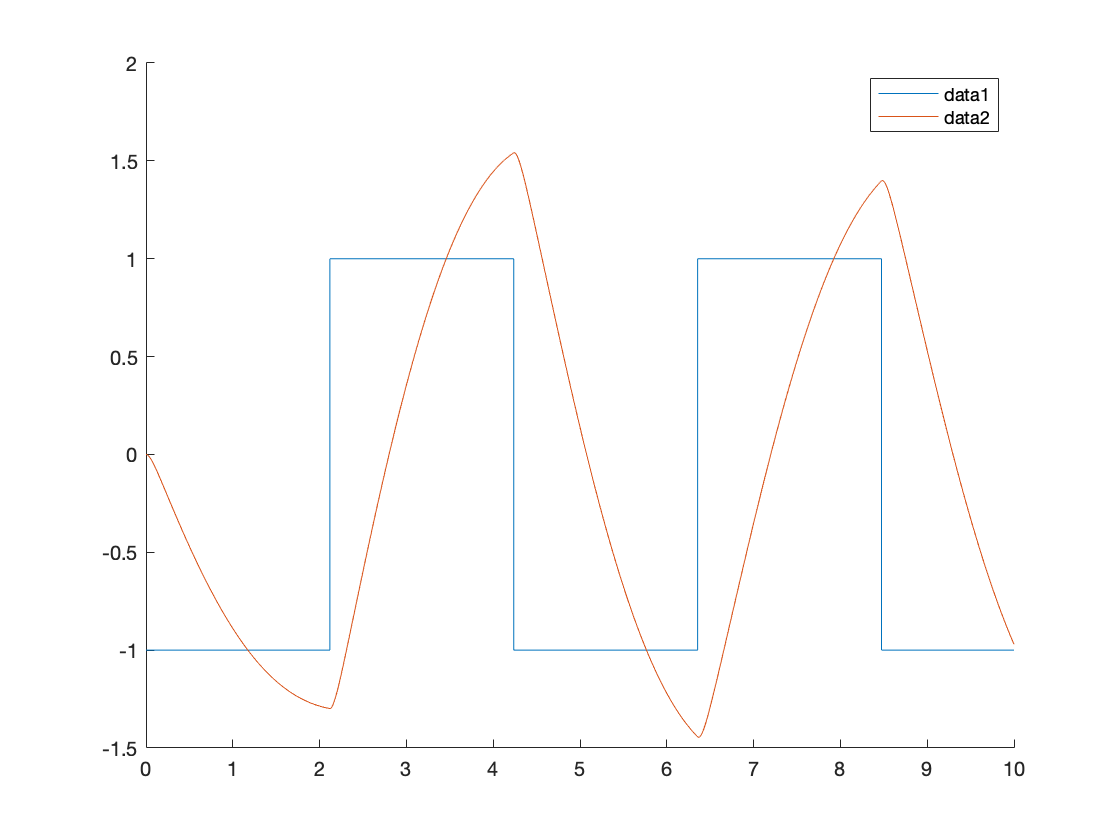

figure
hold on;
plot(refArray(7));
plot(outputArray(7));
legend();
hold off;

kp = round(str2double(get_param(strcat(simTitle, '/plant input'),'P')));
kd = round(str2double(get_param(strcat(simTitle, '/plant input'),'D')));
ki = round(str2double(get_param(strcat(simTitle, '/plant input'),'I')));

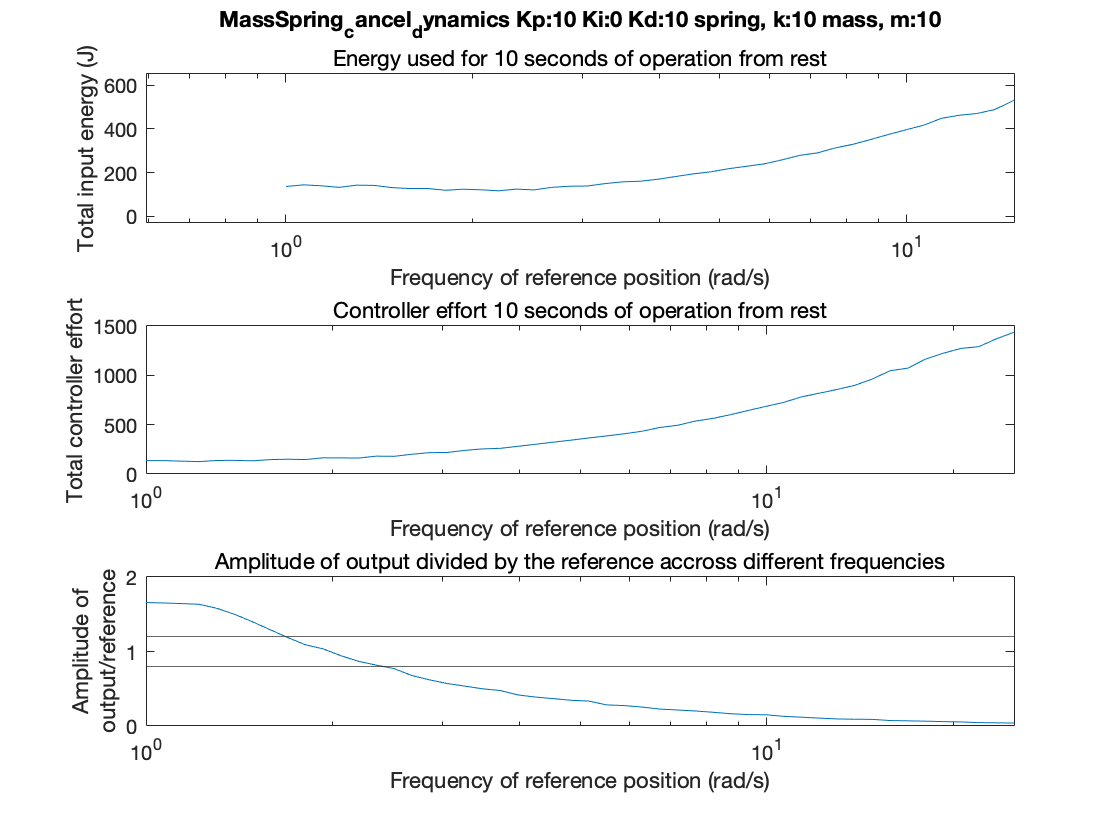


trackingArray   = zeros(length(testOmega), 1);
for i = 1:length(testOmega)
    trackingArray(i) = max(outputArray(i).Data(round(end/2):end))/amplitude;
end

subplot(3,1,1);
semilogx(testOmega, energyArray)
subtitle("Energy used for 10 seconds of operation from rest")
ylabel("Total input energy (J)")
xlabel("Frequency of reference position (rad/s)")
title(strcat(simTitle, " Kp:", string(kp), " Ki:", string(ki), ...
    " Kd:", string(kd), " spring, k:", string(k), " mass, m:",string(m)));

subplot(3,1,2);
semilogx(testOmega, forceArray)
ylabel("Total controller effort")
xlabel("Frequency of reference position (rad/s)")
subtitle("Controller effort 10 seconds of operation from rest");

subplot(3,1,3);
semilogx(testOmega, trackingArray)
hold on;
yline(amplitude *0.8);
yline(amplitude *1.2);
hold off;
ylabel({"Amplitude of","output/reference"});
xlabel("Frequency of reference position (rad/s)")
subtitle("Amplitude of output divided by the reference accross different frequencies");

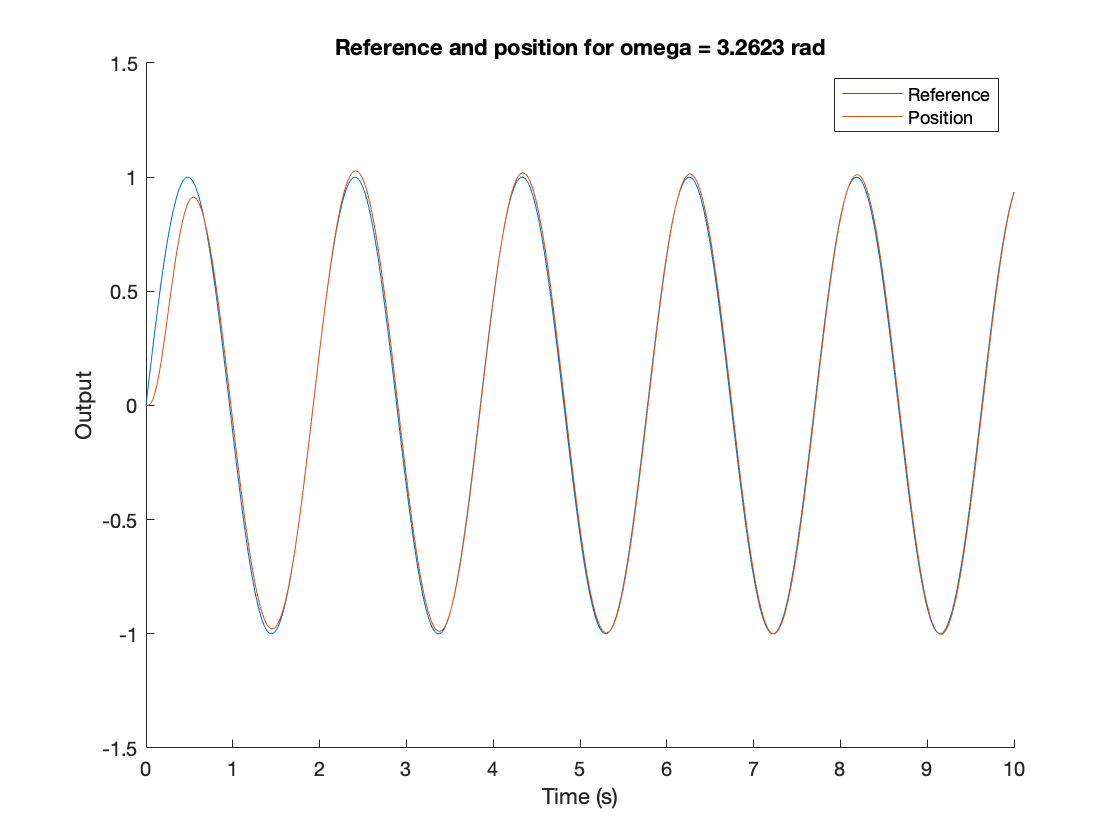

index = 19;
figure
hold on;
plot(refArray(index), "DisplayName", "Reference")
plot(outputArray(index), "DisplayName", "Position")
hold off;
legend;
xlabel("Time (s)");
ylabel("Output");
title(strcat("Reference and position for omega = ", string(testOmega(index)), " rad"));

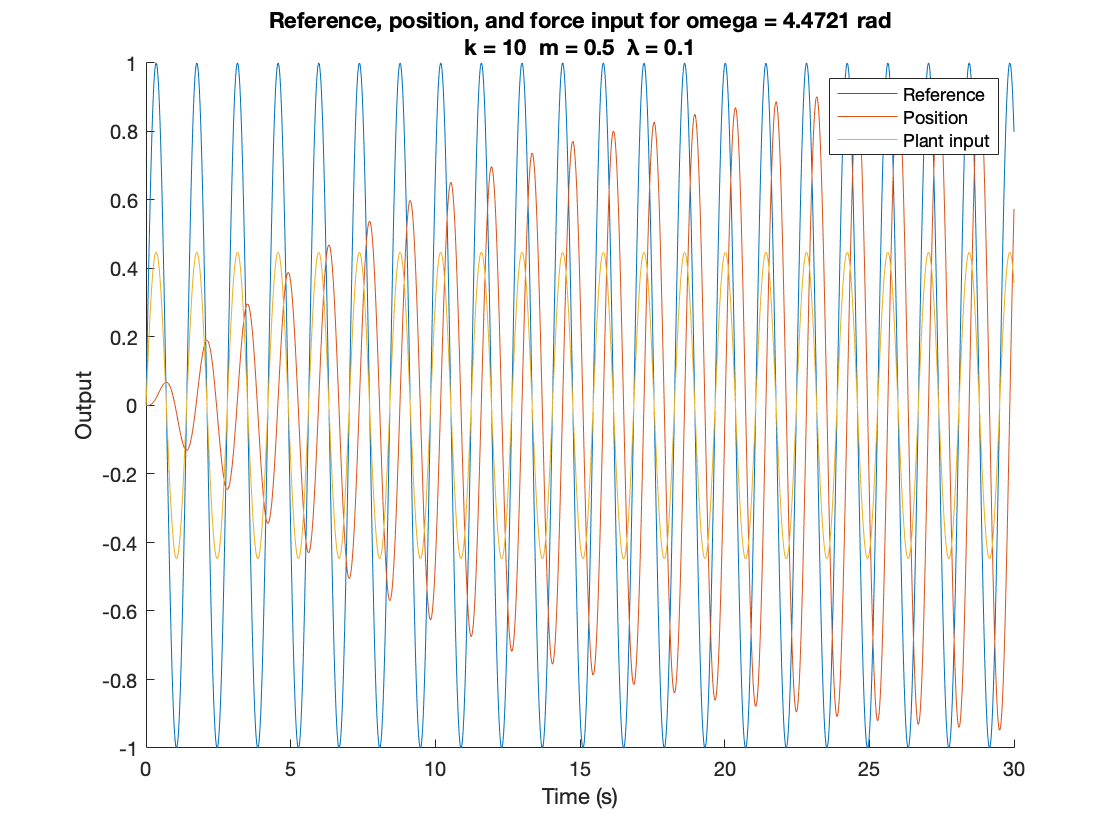

% Open Loop system probing
sim('openLoopExperiments.slx');
set_param('openLoopExperiments','SimMechanicsOpenEditorOnUpdate','off');

OL_omega = sqrt(k/m);
OL_gain = abs(-1*m*OL_omega^2 + l*OL_omega*1i + k);

simTitle = 'openLoopExperiments';
amplitude = 1;
set_param(strcat(simTitle, '/reference'),'Amplitude',string(amplitude));
set_param(strcat(simTitle, '/reference'),'Frequency',string(OL_omega));

simOut = sim(simTitle,'ReturnWorkspaceOutputs','on');
figure
hold on;
plot(simOut.ref, "DisplayName", "Reference")
plot(simOut.pos, "DisplayName", "Position")
plot(simOut.u, "DisplayName", "Plant input")
hold off;
legend;
title({strcat("Reference, position, and force input for omega = ", string(OL_omega), " rad"),strcat("k = ", string(k), "  m = ", string(m), "  λ = ", string(l))});
xlabel("Time (s)");
ylabel("Output");